Lec01-Çalışma

Y = blkdiag(2,[1 2;3 1],5); % create diagonal matrix
X = [1,2,3,4;5,6,7,8;9,10,11,12;13,14,15,16];
Z = vertcat(X,Y);
Z_column = reshape(Z,32,1);
size(Z_column);
A_0 = [2 3; 2 1 ];
B_0 = [2 1;3 1];
C_0 = A_0*B_0;
D_0 = A_0.*B_0;

M = reshape(linspace(11,18,8),[2,2,2]);
single_elem_m = M(1);
from_to_elem_m = M(5:8);
multiple_elem_array_m = M([1,3,4,7]);  %linear indexing array
multiple_elem_matrix_m = M([1,5,2;8,3,2;7,4,6]);  %linear indexing matrix

 3D array: keep rows as same,change column order and third dim order.

T = M([1,2],[2,1],[2,1]);

Printing diamond of stars:

print_diamond;

     *
    ***
   *****
  *******
 *********
 *********
  *******
   *****
    ***
     *


Plotting some graph:

x = linspace(0,2*pi,1000);
y = sin(2*x);
plot(x,y,'k-','linew',2); hold on;
hold on;plot(linspace(0,pi/2,1000),sin(2*linspace(0,pi/2,1000)),'r-','linew',2);

Squeezing arrays:

A = rand(5,5,10);
b = rand(5,1);
c = rand(10,1);

A1 = A(:,:,2);
size(A1);
A1*b;

A2 = A(2,:,:);
A3 = squeeze(A(2,:,:));
size(A2);
size(A3);

A2.*c;
A3*c;

Function handle: is a data type actually. 

Function handles can represent either named or anonymous functions.

D = rand(2); E = rand(2,1);
normal_sub = D-E;
bsx_sub = bsxfun(@minus,D,E); % does elementwise operations
isequal(normal_sub,bsx_sub);

Cells and Cell Arrays:

 F = {14, [1,2;5,10], 'hello world!'};
 class(F);
 class(F{1});
 class(F{2});
 class(F{3});
 elem_F2 = F{2}(2); % column-wise order => gets '4'

Comma-sep list

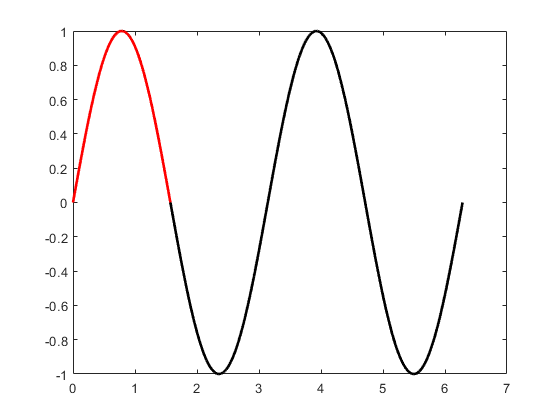

hold off;

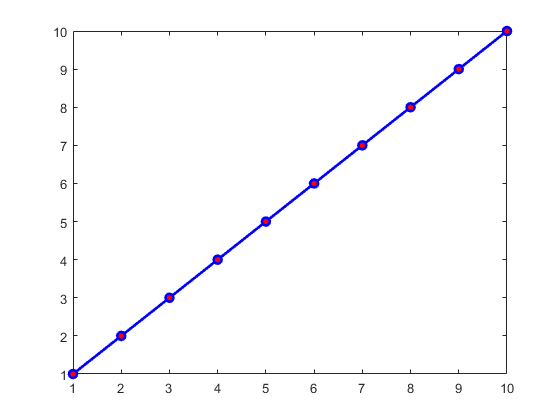

pstr={'bo-','linewidth',2,'markerfacecolor','r'};
plot(1:10,pstr{:})

G = {[1,2;5,4],[0,3,6;1,2,6]};
list_to_func = [G{:}]; % Pass comma−sep list to func

Cell arrays require additional memory to store information describing each cell

 c = {[]}; s=whos('c'); s.bytes;

Structs are like maps in python or java

classes=struct('name',{'CME192','CME292'},'units',{1,2},'grade',{'C','A'});
second_el_struct = classes(2);
fieldnames_ = fieldnames(classes);
getting_field = getfield(classes,'name');
new_classes = rmfield(classes,"grade");

Extra information: creating dynamic field names

current_date = datestr(now,'mmmdd');
dyna_struct = struct();
dyna_struct.(current_date) = 'This is a dynamic field example';
disp(dyna_struct);

    Apr23: 'This is a dynamic field example'



Function Handle (ex: trapezoidal rule)

var_a = exp(1);
trap_f = @(x) var_a*x.^2; % anonymous function 
trap_rule(trap_f,-1,1,1000);

Some examples on anonymous functions:

sqr = @(num) num.^2;
sqrs = sqr(1:4);
integral_ex = integral(@(x) x.^2,0,1);
multi_param_anonymous = @(x,q,w,r) q*x.^2+w*x+r;
multi_param_result = multi_param_anonymous(2,2,3,4);
multi_anonymous = @(const) integral(@(x) x.^2+const*x+const,0,1);
multi_anonymous_result = multi_anonymous(5);
no_input = @() datestr(now);
no_input_result = no_input(); % omitting bracets will create another function handle

% array of anonymous functions
f = {@(x) (x.^2);
     @(y) (y + 10);
     @(x,y) (x.^2 + y + 10)};
anonymous_x = 1;
anonymous_y = 10;
anonymous_res_1 = f{1}(anonymous_x);
anonymous_res_2 = f{2}(anonymous_y);
anonymous_res_3 = f{3}(anonymous_x,anonymous_y);

Unknown number of input/output argument:

% use varargin/varargout
% see funtion_trials.m file, line 15 and 71-78

Due to Fortran ordering, indexing column-wise is much faster than indexing row-wise

(Contiguous memory)

mat = ones(1000, 1000); n = 1e6; %10^6 
tic();
for i=1:n, vec = mat(1,:); end
toc()

Elapsed time is 2.925321 seconds.


tic();
for i=1:n, vec = mat(:,1); end
toc()

Elapsed time is 1.934755 seconds.


Vectorization examples:

i = 0;
for t = 0:.01:10
i = i + 1;
y(i) = sin(t);
end
% this can be written as 
L = sin(0:.01:10);
%%%%% another one %%%%%
vec_n = 100;
vec_M = magic(vec_n);
%{
magic(N) is an N-by-N matrix constructed from the integers
    1 through N^2 with equal row, column, and diagonal sums.
    Produces valid magic squares for all N > 0 except N = 2.
#####THIS ALSO SHOWS EXACT FORMAT OF MULTILINE COMMENTING.#####  
%}
vec_v = vec_M(:,1);
for i = 1:vec_n
vec_M(:,i) = vec_M(:,i) - vec_v
end

M =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


M =            0       -9998
           0        9798
           0        9598
           0       -9398
           0       -9198
           0        8998
           0        8798
           0       -8598
           0       -8398
           0        8198


M =            0       -9998       -9997
           0        9798        9797
           0        9598        9597
           0       -9398       -9397
           0       -9198       -9197
           0        8998        8997
           0        8798        8797
           0       -8598       -8597
           0       -8398       -8397
           0        8198        8197


M =            0       -9998       -9997          -3
           0        9798        9797           3
           0        9598        9597           3
           0       -9398       -9397          -3
           0       -9198       -9197          -3
           0        8998        8997           3
           0        8798        8797           3
           0       -8598       -8597          -3
           0       -8398       -8397          -3
           0        8198        8197           3


M =            0       -9998       -9997          -3          -4
           0        9798        9797           3           4
           0        9598        9597           3           4
           0       -9398       -9397          -3          -4
           0       -9198       -9197          -3          -4
           0        8998        8997           3           4
           0        8798        8797           3           4
           0       -8598       -8597          -3          -4
           0       -8398       -8397          -3          -4
           0        8198        8197           3           4


M =            0       -9998       -9997          -3          -4       -9994
           0        9798        9797           3           4        9794
           0        9598        9597           3           4        9594
           0       -9398       -9397          -3          -4       -9394
           0       -9198       -9197          -3          -4       -9194
           0        8998        8997           3           4        8994
           0        8798        8797           3           4        8794
           0       -8598       -8597          -3          -4       -8594
           0       -8398       -8397          -3          -4       -8394
           0        8198        8197           3           4        8194


M =            0       -9998       -9997          -3          -4       -9994       -9993
           0        9798        9797           3           4        9794        9793
           0        9598        9597           3           4        9594        9593
           0       -9398       -9397          -3          -4       -9394       -9393
           0       -9198       -9197          -3          -4       -9194       -9193
           0        8998        8997           3           4        8994        8993
           0        8798        8797           3           4        8794        8793
           0       -8598       -8597          -3          -4       -8594       -8593
           0       -8398       -8397          -3          -4       -8394       -8393
           0        8198        8197           3           4        8194        8193


M =            0       -9998       -9997          -3          -4       -9994       -9993          -7
           0        9798        9797           3           4        9794        9793           7
           0        9598        9597           3           4        9594        9593           7
           0       -9398       -9397          -3          -4       -9394       -9393          -7
           0       -9198       -9197          -3          -4       -9194       -9193          -7
           0        8998        8997           3           4        8994        8993           7
           0        8798        8797           3           4        8794        8793           7
           0       -8598       -8597          -3          -4       -8594       -8593          -7
           0       -8398       -8397          -3          -4       -8394       -8393          -7
           0        8198        8197           3           4        8194        8193           7


M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8
           0        9798        9797           3           4        9794        9793           7           8
           0        9598        9597           3           4        9594        9593           7           8
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8
           0        8998        8997           3           4        8994        8993           7           8
           0        8798        8797           3           4        8794        8793           7           8
           0       -8598       -8597          -3          -4       -8594       -8593          -7          -8
           0       -8398       -8397          -3          -4       -8394       -8393          -7          -8
           0   

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990
           0        9798        9797           3           4        9794        9793           7           8        9790
           0        9598        9597           3           4        9594        9593           7           8        9590
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190
           0        8998        8997           3           4        8994        8993           7           8        8990
           0        8798        8797           3           4        8794        8793           7           8        8790
           0       -8598       -8597          -3          -4       -8594       -8593          -7          -8       -8590
           0       -8398    

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989
           0        9798        9797           3           4        9794        9793           7           8        9790        9789
           0        9598        9597           3           4        9594        9593           7           8        9590        9589
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -9189
           0        8998        8997           3           4        8994        8993           7           8        8990        8989
           0        8798        8797           3           4        8794        8793           7           8        8790        8789
           0       -8598       -8597          -3          -4     

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -9189         -11
           0        8998        8997           3           4        8994        8993           7           8        8990        8989          11
           0        8798        8797           3           4        8794        8793           7           8        8790      

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -9189         -11         -12
           0        8998        8997           3           4        8994        8993           7           8        8990        8989          11          12
           0        8798        8797           3      

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -9189         -11         -12       -9186
           0        8998        8997           3           4        8994        8993           7           8        8990        8989          11       

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -9189         -11         -12       -9186       -9185
           0        8998        8997           3           4        8994        8993       

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385         -15
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -9189         -11         -12       -9186       -9185         -15
           0        8998       

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385         -15         -16
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -9189         -11         -12       -9186       -

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385         -15         -16       -9382
           0       -9198       -9197          -3          -4       -9194       -9193          -7          -8       -9190       -

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385         -15         -16       -9382       -9381
           0       -9198       -9197          -3          -4       -9194       -

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385         -15         -16       -9382       -9381         -19
           0       -9198       -

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385         -15         -16       -9382       -9381         

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9386       -9385         -15         

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        9577
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9389         -11         -12       -9

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        9577          23
           0       -9398       -9397          -3          -4       -9394       -9393          -7          -8       -9390       -9

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        9577          23          24
           0       -9398       -9397          -3          -4       -9394       -9393         

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        9577          23          24        9574
           0       -9398       -9397          -3         

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        9577          23          24        9574        9573
           0       -9

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        9577          23          24        9574        95

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        9577          23          

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578        95

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        95

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        95

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35
           0        9598        9597           3           4        9594        9593           7           8        9590        95

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36
           0        9598        9597           3           4        9594        9593           7          

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        9762
           0        9598        9597           3           4        9594        95

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        9762        9761
           0        9598        9597           3          

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        9762        9761          39
           0        9598        95

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        9762        9761          39          40
          

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        9762        9761          39          4

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        9762        9761          3

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957         -43
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        9762        976

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957         -43         -44
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          36        976

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957         -43         -44       -9954
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          35          3

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957         -43         -44       -9954       -9953
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        9765          3

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957         -43         -44       -9954       -9953         -47
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        9766        976

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957         -43         -44       -9954       -9953         -47         -48
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          32        976

M =            0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970       -9969         -31         -32       -9966       -9965         -35         -36       -9962       -9961         -39         -40       -9958       -9957         -43         -44       -9954       -9953         -47         -48       -9950
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770        9769          31          3

M = 100×51
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×52
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×53
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×54
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×55
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×56
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×57
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×58
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×59
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×60
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×61
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×62
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×63
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×64
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×65
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×66
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×67
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×68
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×69
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×70
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×71
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×72
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×73
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×74
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×75
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×76
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×77
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×78
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×79
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×80
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×81
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×82
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×83
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×84
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×85
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×86
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×87
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×88
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×89
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×90
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×91
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×92
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×93
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×94
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×95
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×96
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×97
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×98
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×99
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578   

M = 100×100
           0       -9998       -9997          -3          -4       -9994       -9993          -7          -8       -9990       -9989         -11         -12       -9986       -9985         -15         -16       -9982       -9981         -19         -20       -9978       -9977         -23         -24       -9974       -9973         -27         -28       -9970
           0        9798        9797           3           4        9794        9793           7           8        9790        9789          11          12        9786        9785          15          16        9782        9781          19          20        9778        9777          23          24        9774        9773          27          28        9770
           0        9598        9597           3           4        9594        9593           7           8        9590        9589          11          12        9586        9585          15          16        9582        9581          19          20        9578  

% vectorised version => vec_M = bsxfun(@minus,vec_M,vec_v)

When MATLAB arrays passed to a function, only copied to local

workspace when it is modified.Otherwise, entries accessed based on original location in memory. See function_trials.m > line_ 21-24 and 87-101 